**Context:** Prior exploration hints at the possiblity at formulating a method of quickly determining whether a given arm design can reach a target shape by only inspecting the reaction wrenches created at a select few pressure options that form the "edges" or even "vertices" of the control space.

**Goal:** In this document we will investigate

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

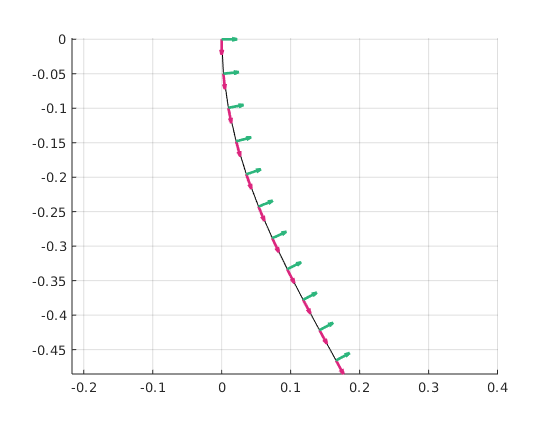

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on
set(gcf, "visible", true)

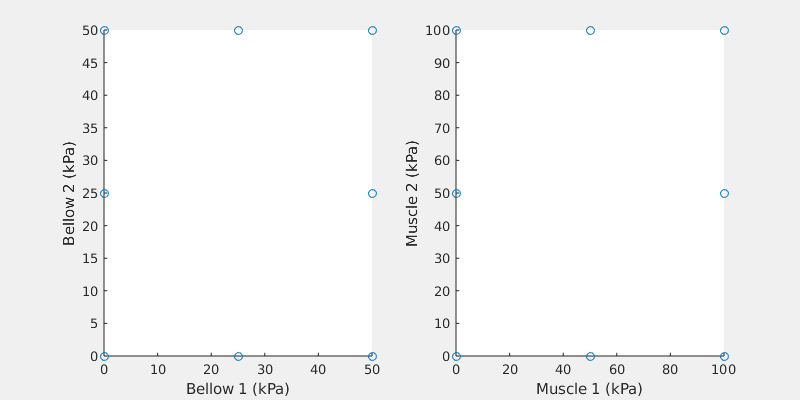

% Clearly our prism is not the full reaction image. But what is the full
% reaction image?
% This begs the question: what is the actual full reaction image?
%
% We can do this in two ways: we can compute the reactions for pressures
% along the edges of the hypercube. OR, we can do a monte-carlo sampling of
% random points in the pressure space

% METHOD 1: Sample a bunch of points in R4 bounded by [0; 0; 0; 0] and [50; 100; 100; 50]
rng(100);
p_max = [50, 100, 100, 50];
N_ps = 100;
ps_bndry = diag(p_max) * betarnd(0.3, 0.3, 4, N_ps); % By using a beta distribution we can bias towards the edges

% METHOD 2: Use the vertices of the pressure space
bitstrings = (dec2bin(0:15) - '0')';
ps_bndry = diag(p_max) * bitstrings;
N_ps = size(ps_bndry, 2);

% % METHOD 3: Use the faces of the pressure space
% N_ps = 30;
% ps_bndry = sample_faces_of_cuboid(N_ps, [50, 100, 100, 50]);
% % And append the vertices
% ps_bndry = [ps_bndry, diag(p_max) * bitstrings];
% N_ps = size(ps_bndry, 2);

% METHOD 4: Use the edges of the pressure space
N_ps_per_edge = 2;
ps_bndry = sample_edges_of_cuboid(N_ps_per_edge, [50, 100, 100, 50]);
N_ps = size(ps_bndry, 2);

figure("Position", [0, 0, 800, 400])
subplot(1, 2, 1)
scatter(ps_bndry(1, :), ps_bndry(4, :));
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
scatter(ps_bndry(2, :), ps_bndry(3, :));
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

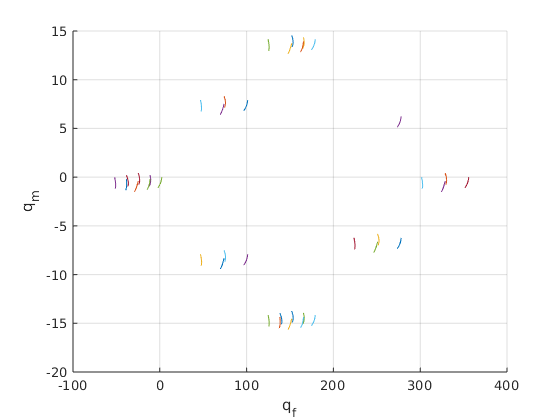

mat_s_bndry = repmat(s, [N_ps, 1]);

qs_bndry = zeros(3, N_poses, N_ps);
for i = 1 : N_ps
    qs_bndry(:, :, i) = calc_reaction_wrench(segment_twists, ps_bndry(:, i), struct_design);
end

[paths_af_bndry, paths_am_bndry] = compute_reaction_traces(ps_bndry, segment_twists, struct_design);

figure()
hold on
plot3(paths_af_bndry, paths_am_bndry, mat_s_bndry);
xlabel("q_f")
ylabel("q_m")
grid on
set(gcf, "Visible", true)

One thing that is noteworthy: we can immediately tell from this graph that not all pressures have equal change in reactions along the arm (the "hairs" don't all move in the same direction). Thus there is not an easy and universal way to check if the "direction" of the hair alignts with what is possible.

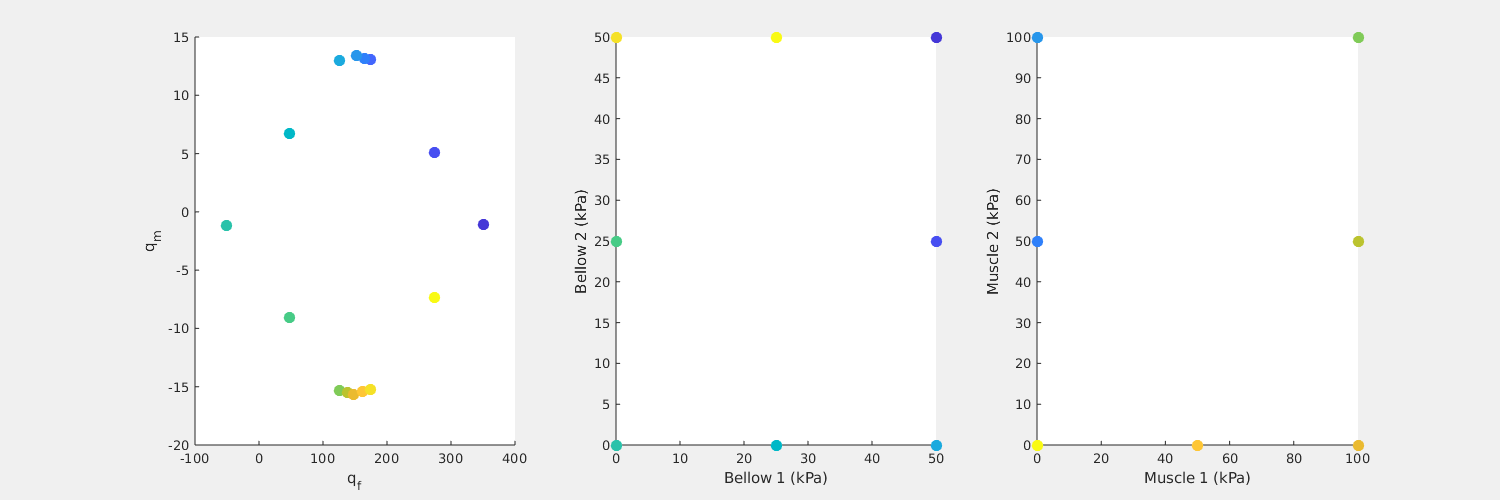

% Find the points that are on the outline of the base level, and then find
% their corresponding pressures. This will tell us which pressures to focus
% on.
i_bnd_as = boundary(paths_af_bndry(1, :)', paths_am_bndry(1, :)', 0.1);
c = linspace(1, 10, length(i_bnd_as));

figure("Position", [0, 0, 1500, 500])
subplot(1, 3, 1);
scatter(paths_af_bndry(1, i_bnd_as), paths_am_bndry(1, i_bnd_as), 75, c, "filled");
xlabel("q_f")
ylabel("q_m")

subplot(1, 3, 2)
scatter(ps_bndry(1, i_bnd_as), ps_bndry(4, i_bnd_as), 75, c, "filled");
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 3, 3)
scatter(ps_bndry(2, i_bnd_as), ps_bndry(3, i_bnd_as), 75, c, "filled");
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

### **Test 1**

**Question:** For the given arm design, shape, and load, the pressures whose reactions bound all reactions at s=0 still bound the reactions for any other 0 < s < 1?

**Hypothesis:** Yes. This would imply that for he given arm design, shape, and load, a naively constructed reaction prism is a valid method of determining shape attainability.

% Create the test dataset
N_test_ps = 1000;
p_max = [50, 100, 100, 50];
ps_test = diag(p_max) * unifrnd(0, 1, 4, N_test_ps); 

a_tests = zeros(3, N_poses, N_test_ps);
for i = 1 : N_test_ps
    a_tests(:, :, i) = calc_reaction_wrench(segment_twists, ps_test(:, i), struct_design);
end
[paths_af_test, paths_am_test] = compute_reaction_traces(ps_test, segment_twists, struct_design);

is_bounded = false(N_poses, N_test_ps);
for i_s = 1 : N_poses
    % Check that the pressures that bounded the reactions at s=0 still
    % bound at 0 < s < 1
    query_af = paths_af_test(i_s, :);
    query_am = paths_am_test(i_s, :);
    
    boundary_af = paths_af_bndry(i_s, i_bnd_as);
    boundary_am = paths_am_bndry(i_s, i_bnd_as);

    is_bounded(i_s, :) = inpolygon(query_af, query_am, boundary_af, boundary_am);
end

all_bounded = all(is_bounded);
fprintf("Number of pressures whose reactions are fully bounded within: %d / %d = %.2f%%", nnz(all_bounded), N_test_ps, 100*nnz(all_bounded)/N_test_ps);

Number of pressures whose reactions are fully bounded within: 1000 / 1000 = 100.00%

% What are the outlier pressures?
ps_test(:, ~all_bounded)


ans =

  4×0 empty double matrix



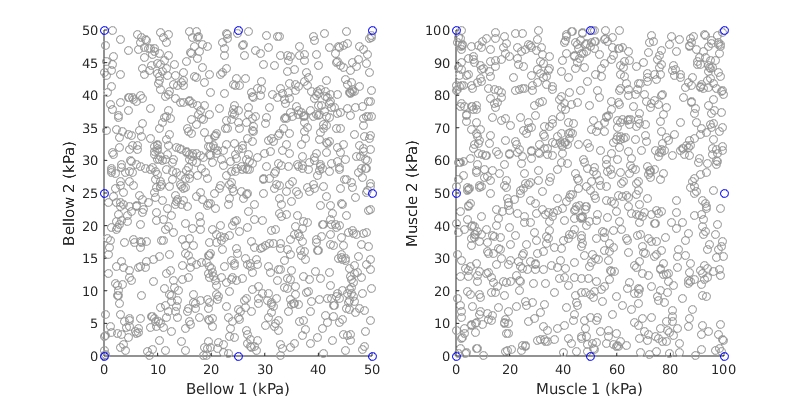

gray = [150,150,150]/255;
% Plot the outlier reactions and/or pressures
figure("Position", [0, 0, 800, 400])
subplot(1, 2, 1)
hold on
scatter(ps_test(1, :), ps_test(4, :), [], gray);
scatter(ps_bndry(1, :), ps_bndry(4, :), [], 'b');
scatter(ps_test(1, ~all_bounded), ps_test(4, ~all_bounded), 'filled');
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
hold on
scatter(ps_test(2, :), ps_test(3, :),[], gray);
scatter(ps_bndry(2, :), ps_bndry(3, :), [], 'b');
scatter(ps_test(2, ~all_bounded), ps_test(3, ~all_bounded), 'filled');
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

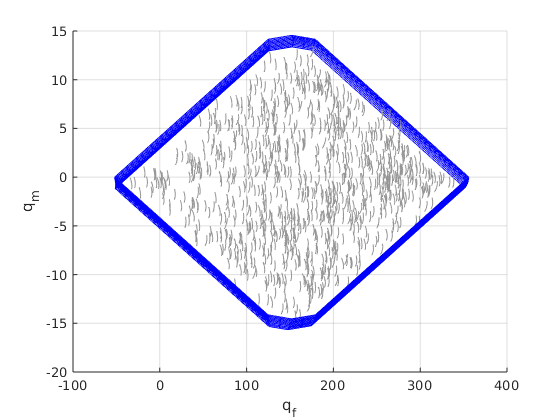

figure()
hold on
mat_s = repmat(s, [length(i_bnd_as), 1]);
mat_s_test = repmat(s, [N_test_ps, 1]);
plot3(paths_af_bndry(:, i_bnd_as)', paths_am_bndry(:, i_bnd_as)', s, 'b');
plot3(paths_af_bndry(:, i_bnd_as)', paths_am_bndry(:, i_bnd_as)', mat_s, 'b');
plot3(paths_af_test, paths_am_test, mat_s_test, "color", gray);
plot3(paths_af_test(:, ~all_bounded), paths_am_test(:, ~all_bounded), mat_s_test(~all_bounded, :), 'r')
xlabel("q_f")
ylabel("q_m")
zlabel("s")
grid on
set(gcf, "Visible", true)

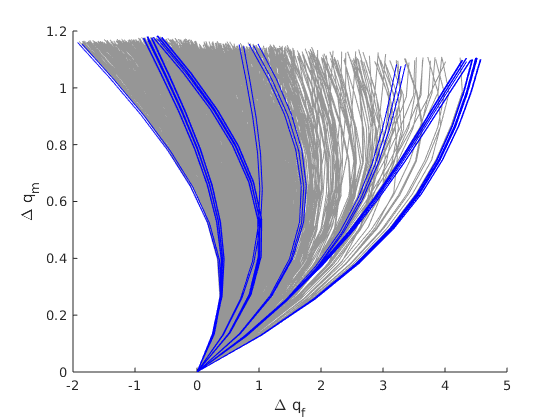

% Compare the "directions" of all of the hairs
displacements_af_test = paths_af_test - paths_af_test(1, :);
displacements_am_test = paths_am_test - paths_am_test(1, :);

displacements_af_boundary = paths_af_bndry - paths_af_bndry(1, :);
displacements_am_boundary = paths_am_bndry - paths_am_bndry(1, :);

figure()
hold on
plot(displacements_af_test, displacements_am_test, color=gray);
plot(displacements_af_boundary, displacements_am_boundary, color='b');
xlabel("\Delta q_f")
ylabel("\Delta q_m")
set(gcf, "Visible", true)

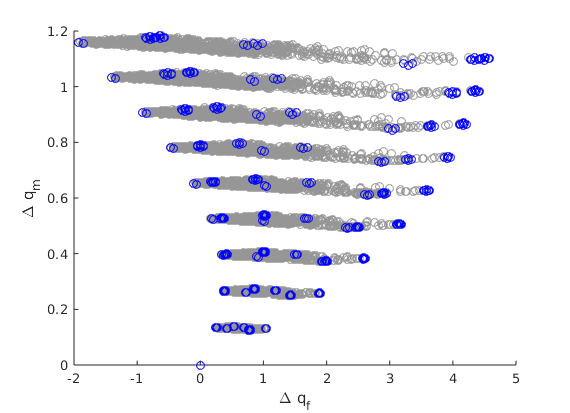

figure()
hold on
plot(displacements_af_test, displacements_am_test, "o", color=gray);
plot(displacements_af_boundary, displacements_am_boundary, "o", color='b');
xlabel("\Delta q_f")
ylabel("\Delta q_m")
set(gcf, "Visible", true)

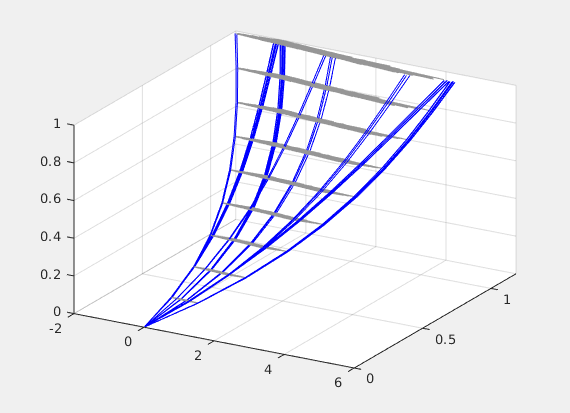

figure("Visible", true)
hold on;

mat_s_all_bnd_pressures = repmat(s, [size(displacements_af_boundary, 2), 1]);

plot3(displacements_af_test', displacements_am_test', mat_s_test, color=gray);
plot3(displacements_af_boundary, displacements_am_boundary, mat_s_all_bnd_pressures, color='b');
grid on
view(30, 30)

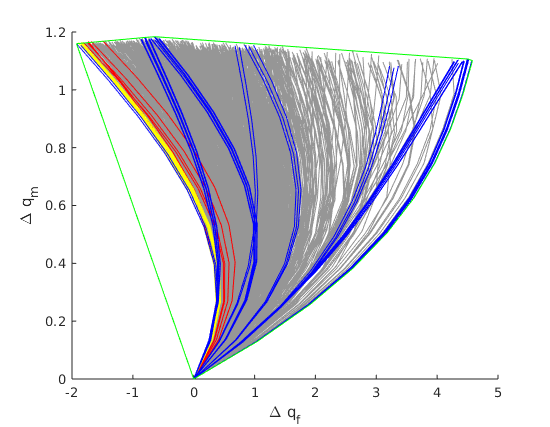

% Question: Which pressures correspond to reaction traces not bounded by
% the ones from the pressure boundary?
i_bounds_displacements_boundary = boundary(displacements_af_boundary(:), displacements_am_boundary(:), 0);
bound_disps_af_boundary = displacements_af_boundary(i_bounds_displacements_boundary);
bound_disps_am_boundary = displacements_am_boundary(i_bounds_displacements_boundary);

% Find traces where any point is outside of the convex hull of the blue
disps_in_bounds = inpolygon(displacements_af_test, displacements_am_test, bound_disps_af_boundary, bound_disps_am_boundary);
mask_disps_out = ~all(disps_in_bounds, 1);

% Get the left-most 10 displacements and find what pressures created them
[~, i_sort] = sort(displacements_af_test(end, :));
i_left_most = i_sort(1:10);

figure()
hold on
plot(displacements_af_test, displacements_am_test, color=gray);
plot(displacements_af_test(:, mask_disps_out), displacements_am_test(:, mask_disps_out), 'r');
plot(displacements_af_test(:, i_left_most), displacements_am_test(:, i_left_most), 'y');
plot(displacements_af_boundary, displacements_am_boundary, color='b');
plot(bound_disps_af_boundary, bound_disps_am_boundary, 'g')
xlabel("\Delta q_f")
ylabel("\Delta q_m")
set(gcf, "Visible", true)

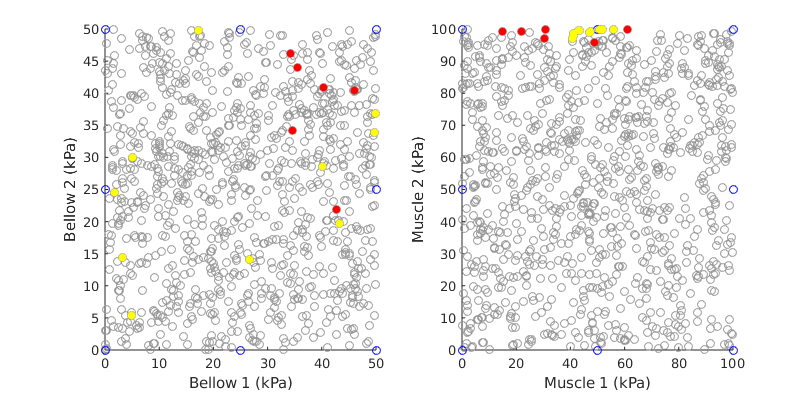


figure("Position", [0, 0, 800, 400])
subplot(1, 2, 1)
hold on
scatter(ps_test(1, :), ps_test(4, :), [], gray);
scatter(ps_bndry(1, :), ps_bndry(4, :), [], 'b');
scatter(ps_test(1, ~all_bounded), ps_test(4, ~all_bounded), 'filled');
scatter(ps_test(1, mask_disps_out), ps_test(4, mask_disps_out), 'r', 'filled')
scatter(ps_test(1, i_left_most), ps_test(4, i_left_most), 'y', 'filled')
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
hold on
scatter(ps_test(2, :), ps_test(3, :),[], gray);
scatter(ps_bndry(2, :), ps_bndry(3, :), [], 'b');
scatter(ps_test(2, ~all_bounded), ps_test(3, ~all_bounded), 'filled');
scatter(ps_test(2, mask_disps_out), ps_test(3, mask_disps_out), 'r', 'filled')
scatter(ps_test(2, i_left_most), ps_test(3, i_left_most), 'y', 'filled')
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

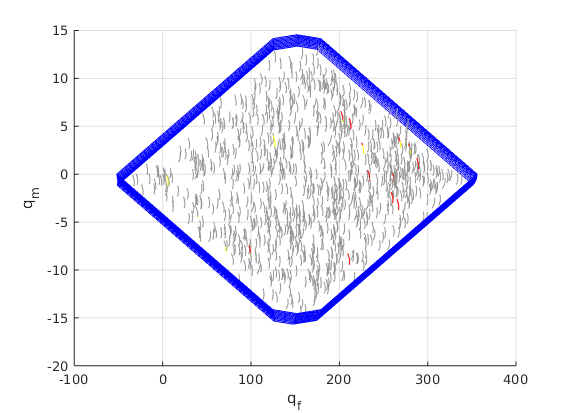

figure()
hold on
mat_s = repmat(s, [length(i_bnd_as), 1]);
mat_s_test = repmat(s, [N_test_ps, 1]);
plot3(paths_af_bndry(:, i_bnd_as)', paths_am_bndry(:, i_bnd_as)', s, 'b');
plot3(paths_af_bndry(:, i_bnd_as)', paths_am_bndry(:, i_bnd_as)', mat_s, 'b');
plot3(paths_af_test, paths_am_test, mat_s_test, "color", gray);
plot3(paths_af_test(:, mask_disps_out), paths_am_test(:, mask_disps_out), mat_s_test(mask_disps_out, :), 'r')
plot3(paths_af_test(:, i_left_most), paths_am_test(:, i_left_most), mat_s_test(i_left_most, :), 'y')
xlabel("q_f")
ylabel("q_m")
zlabel("s")
grid on
set(gcf, "Visible", true)

#### Test 1a

We now have an intuitive heuristic for determining whether a reaction requirement is actually attainable - for each s, the reactions themselves need to be enclosed by the reactions from the boundary pressures, and the relative reactions need to be within the boundary relative reactions.

Let us now implement this heuristic in a function. Crucially we are interested in knowing

- What are the false positive and false negative rates of this detection method?

- How fast is it?

error("Remove this to run this block")

Remove this to run this block

v_attainable = zeros(N_test_ps, 1);

tic
p_bounds = [50; 100; 100; 50];
for i = 1 : N_test_ps
    v_attainable(i) = check_reactions_attainable_fast(a_tests(:, :, i), segment_twists, struct_design, p_bounds);
end
toc
fprintf("False negative rate: %.2f%%", 100 * nnz(~v_attainable) / N_test_ps);

#### Test 1b

Simple false positive test:

In this test test if the above arm design held at the above shape (given by the same `segment_twists` variable) can attain the target reactions given by -a_tests, which is the negative of all of the actually attainable reaction traces.

We cannot consider this to be a comprehensive test for false-positives. A true test needs to consider arbitrary reaction requirements across different arm dimensions and shapes to confidently establish that this method does not contain false-positives.

v_attainable = zeros(N_test_ps, 1);
profile on
tic
p_bounds = [50; 100; 100; 50];
for i = 1 : N_test_ps
    v_attainable(i) = check_reactions_attainable_fast(-a_tests(:, :, i), segment_twists, struct_design, p_bounds);
end
toc

Elapsed time is 23.533707 seconds.


profile viewer
fprintf("False positive rate: %.2f%%", 100 * nnz(v_attainable) / N_test_ps);

False positive rate: 0.00%

### Test 2

Our goal is to use a small number K of pressures to determine a heuristic that can classify whether a given set of reactions along the arm $q_{\textrm{rec}}$ is within the image of the input pressure space under the internal reaction function: $q_{\textrm{rec}} \stackrel{?}{\in} a(P)$. In other words, we want to know if there exists $p \in P$ such that $q_{\textrm{rec}} = a(p)$ for some p.

So far we have investigated various methods for creating such a heuristic by examining conditions that are shared for all points in $a(P)$, such as the fact that they are all bounded by the $a(\partial P)$, and that the displacements $a(P) - a_0(P) \in \Delta a(\partial P)$ where $\Delta a(\partial P) = \{a(p) - a_0(p) \mid p \in \partial P\}$.

However, we have not yet been able to genuinely test the validity of such a heuristic. The converse is not the contrapositive: "$q \in a(P)$ then $q \in a(\partial P)$ and $q-q_0 \in \Delta a(\partial P)$" being true does not make its converse "If $q-q_0 \in \Delta a(\partial P)$ and $q \in a(\partial P)$ then $q \in a(P)$" true. Put more clearly, while we have a necessary condition for attainability, we do not have a sufficient condition. It is conceivable that there exists $q \in \mathbb{R}^{20}$ such that both conditions 1 and 2 are true yet $q\notin a(P)$. 

Thus, we need to test if our heuristics are actually true for the converse: that if any arbitrary $q \in \mathbb{R}^{20}$ meets a set of conditions 1, 2, ..., n, then $q \in a(P)$ is true.

Note: the actual set of test $q$ do not need to be arbitrary $q \in \mathbb{R}^{20}$. In reality we only need to consider $q \in E$ where $L = \{ Q \in \mathbb{R}^{3} \mid E(Q)\}$ is the set of possible reaction requirements for a given shape, which is determined by computing the externally induced load for a shape for any arbitrary forces in R^n.

#### Test 2a: Accurately evaluating the attainability of a reaction

To validate our heuristic, we need a method of determining whether a given $q$ is actually attainable.

I have implemented a function `check_reactions_attainable() `which determines if a set of reactions along an arm $q$ is attainable by searching for a pressure to produce reaction wrenches that most closely match the specified ones. If the closest possible reactions are close to within a threshold, then it is deemed attainable.

reachable_qs = -a_tests(:, :, 1:100:end);
N_tests = size(reachable_qs, 3);
fprintf("Number of reactions to test: %d", N_tests);

Number of reactions to test: 10


tic
[v_attainable, min_dist, p_solns] = check_reactions_attainable(reachable_qs, segment_twists, struct_design, p_bounds, 1e-3);
toc

Elapsed time is 11.815771 seconds.


fprintf("False negative rate: %.2f%%", 100* nnz(~v_attainable) / N_tests);

False negative rate: 0.00%

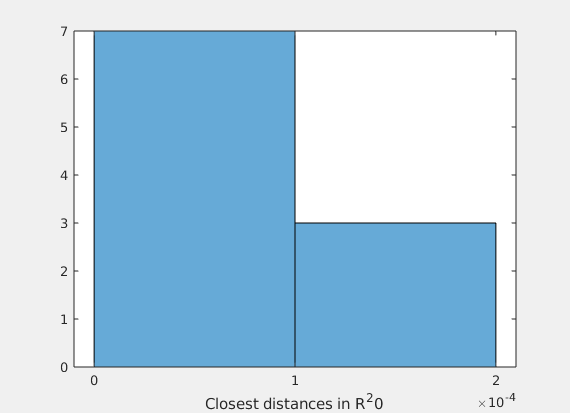

figure("visible", true)
histogram(min_dist);
xlabel("Closest distances in R^20")

With the methadology of this test for reaction attainability, it is impossible for a false positive to occur: any reaction that tests true must have a pressure that can produce a matching reaction.

The above experiment with running this test on a thousand reactions that are attainable hopefully shows that this test also has a very false negative rate - out of a thousand actually reachable reactions, all 97% of them tested positive. Thus we can confirm that this method of determining attainability of a reaction is fairly robust.');

#### Test 2b: Attainability of sampled tip loads

Now let us test attainbility on an actual test set of reactions: an arbitrarily generated set of reaction requirements

% Generate a set of test tip forces
F_x_scale = 10;
F_y_scale = 10;
tau_scale = 5;
K_scales = diag([F_x_scale, F_y_scale, tau_scale]);

rng(100);
N_test_Qs = 100;
Q_tests = K_scales* (rand(3, N_test_Qs) - 0.5);

q_tests = zeros(3, N_poses, N_test_Qs);
for i_test = 1 : N_test_Qs
    Q_test_i = Q_tests(:, i_test);
    q_tests(:, :, i_test) = calc_external_wrench(segment_twists, Q_test_i, g_0);
end


% Check how many of these q_tests are actually reachable
tic
[v_attainable, min_dist] = check_reactions_attainable(q_tests, segment_twists, struct_design, p_bounds, 2e-3);
toc

Elapsed time is 51.363628 seconds.


n_attainable = nnz(v_attainable);
fprintf("Number of attainable tip loads: %d out of %d", n_attainable, N_test_Qs);

Number of attainable tip loads: 0 out of 100

Here we see that of the arm loads produced by a random sampling of 10 tip loads, the arm is capable of producing none of them.

This may seem surprising because as we saw earlier the arm is capable of sustaining a large range of internal reactions at this shape, as we saw in the reachable-reaction-space prism.

However, this actually isn't surprising for the following reasons:

- We've seen already in the control/optimization based valid design space test that this tip pose and full shape is impossible for any arm in the valid design space. 

- While the arm can produce a wide range of reactions, these reactions are only in a set of "directions" determined by the shape of the arm. The actual force has limited control over the reactions it produces.

Suggested next steps:

- Run this same test with a shape that is actually attainable for some tip loads. That way we can actually do some more meaningful classification.

- Better understand the space of arm reactions that can be induced by tip loads when the arm is held in a given shape

#### Test 2c

We have determined that 

#### Test 3a

Based on the analysis so far, we would expect the presence of false positives: a "zig-zagging" trace going in the general direction of all truly attainable traces would be enclosed by both the overall boundary and the direction cone. Yet, these potential false positives do not truly pollute our results. Why?

In this test we take a single arm target shape and apply a large number of different randomly sampled tip loads to it, to attempt to generate "false positives" - reaction requirement traces that satisfy our simplified condition for attainability yet are not truly attainable.

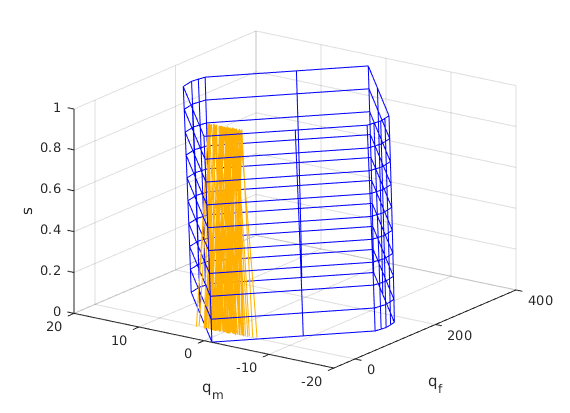

[tests_qf, tests_qm] = mat_wrenches_to_traces(q_tests);

mat_s = repmat(s, [length(i_bnd_as), 1]);
mat_s_Q_samples = repmat(s, [N_test_Qs, 1]);

figure()
hold on
plot3(paths_af_bndry(:, i_bnd_as)', paths_am_bndry(:, i_bnd_as)', s, 'b');
plot3(paths_af_bndry(:, i_bnd_as)', paths_am_bndry(:, i_bnd_as)', mat_s, 'b');
yellow = [255 176 0] / 255;
plot3(tests_qf, tests_qm, mat_s_Q_samples', "color", yellow)

%plot3(paths_af_test, paths_am_test, mat_s_test, "color", gray);
%plot3(paths_af_test(:, ~all_bounded), paths_am_test(:, ~all_bounded), mat_s_test(~all_bounded, :), 'r')
xlabel("q_f")
ylabel("q_m")
zlabel("s")
grid on
set(gcf, "Visible", true)
view(-55, 25)

Some of these reactions are bounded within the prism, but we know they are not reachable. This is likely because they fail the second condition: their displacements are not within the bound of reachable reaction-displacements.

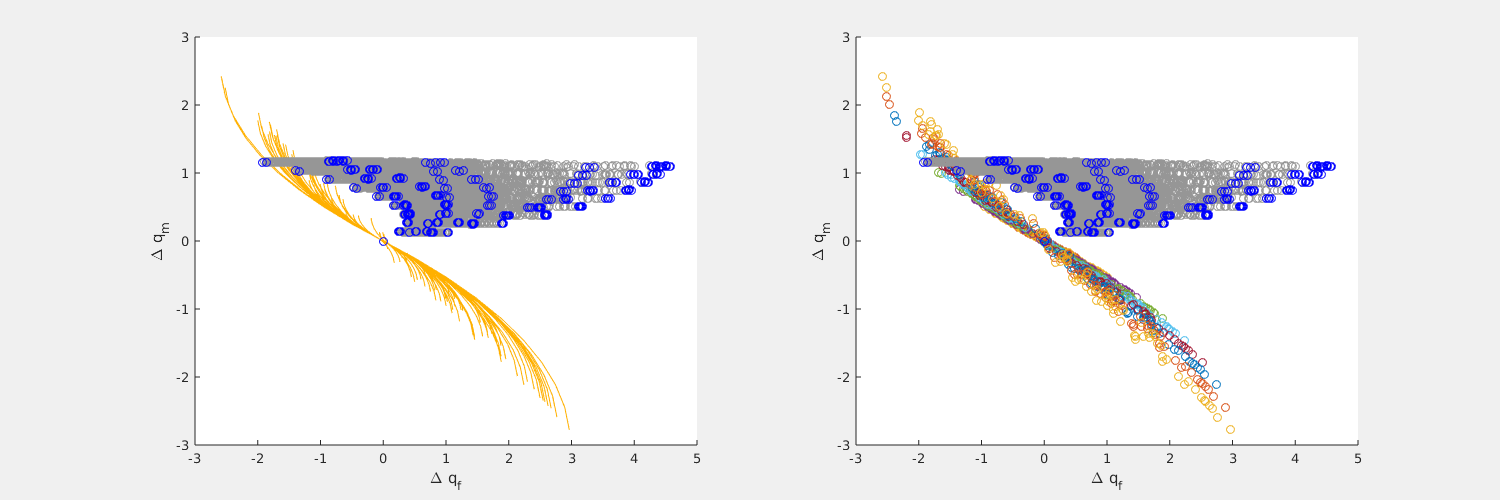

% Plot displacements of the external load
displacements_qf_test = tests_qf - tests_qf(1, :);
displacements_qm_test = tests_qm - tests_qm(1, :);

figure("Position", [0, 0, 1500, 500], "Visible", true)
subplot(1, 2, 1)
hold on
plot(displacements_qf_test, displacements_qm_test, color=yellow);
plot(displacements_af_test, displacements_am_test, "o", color=gray);
plot(displacements_af_boundary, displacements_am_boundary, "o", color='b');
%plot(bound_disps_af_boundary, bound_disps_am_boundary, 'g')
xlabel("\Delta q_f")
ylabel("\Delta q_m")
set(gcf, "Visible", true)

subplot(1, 2, 2)
hold on
scatter(displacements_qf_test', displacements_qm_test', color=yellow);
plot(displacements_af_test, displacements_am_test, "o", color=gray);
plot(displacements_af_boundary, displacements_am_boundary, "o", color='b');
% plot(displacements_af_boundary, displacements_am_boundary, color='b');
% plot(bound_disps_af_boundary, bound_disps_am_boundary, 'g')
xlabel("\Delta q_f")
ylabel("\Delta q_m")

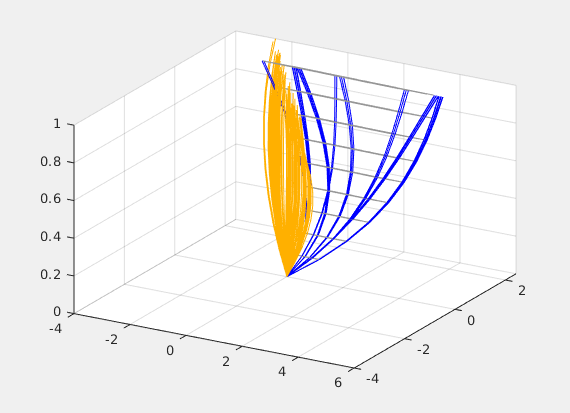

figure("Visible", true);
hold on;
plot3(displacements_af_test', displacements_am_test', mat_s_test, color=gray);
plot3(displacements_af_boundary, displacements_am_boundary, mat_s_all_bnd_pressures, color='b');
plot3(displacements_qf_test, displacements_qm_test, mat_s_Q_samples, color=yellow);
grid on;
view(30,30)

#### Test 3b

It appears that for this shape (and many others), the vast majorities of tip-loads will not deform the arm into the target shape for any pressure in the actuation space. 

However, a binary "true/false" measure on attainability is not very satisfying. We can clearly tell that some shapes are more attainable than others, and may want to find ones to continue the search in the direction to find shapes that are even more attainable.

Thus, we need a metric that is more granular. A starting point is to measure just how "un-attainable" a given reaction requirement trace is, which can just be based on the distance from each point in the reaction trace to the closest point to it in the attainable sets.

% Choose a representative requirement trace
displacements_q_choice = [displacements_qf_test(:, 1)'; displacements_qm_test(:, 1)'];
set(gcf, "Visible", true)

min_dists = zeros(10, 1);
closest_pts = zeros(2, 10);
weights = cell(1, 10);
tic
for i = 2 : size(displacements_q_choice, 2)
    vertices_i = [displacements_af_boundary(i, :); displacements_am_boundary(i, :)];
    i_conv_hull = boundary(vertices_i(1, :)', vertices_i(2, :)', 0);
    conv_hull_vertices_i = vertices_i(:, i_conv_hull);
    
    [min_dists(i), closest_pts(:, i), weights{i}] = distance_to_convex_set(displacements_q_choice(:, i), conv_hull_vertices_i);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

toc

Elapsed time is 0.277919 seconds.


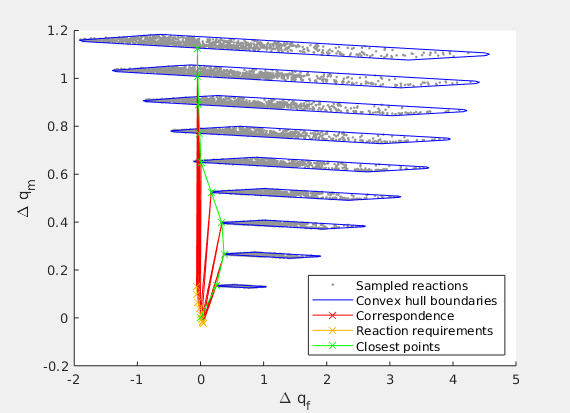

figure("Visible", true)
hold on
plot(displacements_af_test(:), displacements_am_test(:), ".", color=gray, displayname="Sampled reactions");
plot(0, 0, "b", displayname="Convex hull boundaries")
for i = 2 : size(displacements_q_choice, 2)
    i_conv_hull = boundary(displacements_af_boundary(i, :)', displacements_am_boundary(i, :)', 0);
    plot(displacements_af_boundary(i, i_conv_hull)', displacements_am_boundary(i, i_conv_hull), "-", color="b", handlevisibility="off");
end
closest_pairs_f = [displacements_qf_test(:, 1)'; closest_pts(1, :)];
closest_pairs_m = [displacements_qm_test(:, 1)'; closest_pts(2, :)];

plot(closest_pairs_f(:), closest_pairs_m(:), "rx-", displayname="Correspondence");
plot(displacements_qf_test(:, 1), displacements_qm_test(:, 1), "x-", color=yellow, displayname="Reaction requirements");
plot(closest_pts(1, :), closest_pts(2, :), "x-", color="green", displayname="Closest points");

legend(location="southeast")
xlabel("\Delta q_f")
ylabel("\Delta q_m")

function points = sample_faces_of_cuboid(N_points, scales)
    N_dims = length(scales);

    faces = randi([1, 2*N_dims], [1, N_points]);
    points = rand([N_dims, N_points]);
    for i = 1 : N_points
        face_i = faces(i); % Face whose point value to fix at 1 
        fixed_val = 0;
        if face_i > N_dims
            fixed_val = 1;
            face_i = mod(face_i, N_dims);
            face_i = face_i+1;
        end
        points(face_i, i) = fixed_val;
    end

    points = diag(scales) * points;
end